clc; clear; close all;
inputFileName = "single_drone.m" %Input scenario you want to simulate. It has to be an .m file. It has to be in scenarios directory.

inputFileName = "single_drone.m"

inputFileName = fullfile('scenarios',inputFileName) %creating a file path

inputFileName = "scenarios\single_drone.m"

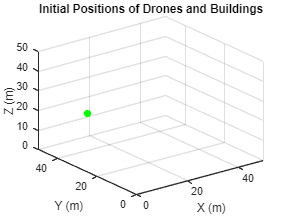

run(inputFileName) %running scenario file


outputFileName = "single_drone_simulation_data.mat"; %Input filname for simulation output data. It has to be .mat format.

outputFileName = "single_drone_simulation_data.mat"

outputFileName = fullfile('output',outputFileName);

outputFileName = "output\single_drone_simulation_data.mat"

Pętla symulacji

% === STORAGE VARIABLES ===
tIndex = 1:numTimeSteps;
allDroneData = struct('timeIndex', num2cell(tIndex), 'droneData', droneData);
allSoundLevels = zeros(numTimeSteps, gridSize, gridSize, gridSize);

% === SIMULATION LOOP ===
for tIndex = 1:numTimeSteps
    t = (tIndex - 1) * timeStep;
    
    % Update Positions and Velocities
    allDroneData(tIndex).droneData = droneData;
    
    % Displaying timestep
    disp(tIndex)

    % Calculate Sound Level Distribution
    L_total = zeros(gridSize, gridSize, gridSize);
    
    for i = 1:numDrones
        drone = droneData(i);
        dronePos = drone.Pos;
        velocity = drone.Vel;
        L_s = drone.SoundLevel;  % Use specific sound level per drone type

        % Calculate direct path sound levels
        L_direct = calculateDirectPath(X, Y, Z, dronePos, L_s, freq, velocity, speedOfSound, pressure, temperature, humidity);

        if ~isempty(buildings)
            % Calculate wall reflections
            L_reflected = getWallReflectionsSoundLevel(X, Y, Z, dronePos, L_s, freq, buildings, pressure, temperature, humidity);
            % Combine direct and reflected contributions
            L_drone = 10 * log10(10.^(L_direct / 10) + 10.^(L_reflected / 10));

        else
            L_drone = L_direct;
        end
       
        L_total = 10 * log10(10.^(L_total / 10) + 10.^(L_drone / 10));
    end

    % Store sound levels
    allSoundLevels(tIndex, :, :, :) = L_total;

    % Update drone positions
    droneData = getDronesPositionAndVel(droneData,timeStep);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51




% === SAVE SIMULATION DATA ===

save(outputFileName, 'allDroneData', 'allSoundLevels', ...
     'xMax', 'yMax', 'zMax', 'totalTime', 'timeStep', 'gridSize', 'x', 'y', 'z','buildings');

fprintf('Simulation completed and data saved as %s',outputFileName);

Simulation completed and data saved output\single_drone_simulation_data.mat in output folder

% === SOUND CALCULATION FUNCTIONS ===
function L_direct = calculateDirectPath(X, Y, Z, dronePos, L_s, freq, velocity, speedOfSound, pressure, temperature, humidity)
    % Extract drone position
    x_d = dronePos(1);
    y_d = dronePos(2);
    z_d = dronePos(3);
    
    % Calculate distance to all grid points
    r = sqrt((X - x_d).^2 + (Y - y_d).^2 + (Z - z_d).^2);
    r(r < 1) = 1; % Avoid singularity (minimum distance of 1 meter)

    % Geometric spreading
    L_geom = getGeometricSpreadingSoundLevel(L_s, r);
    
    % Air absorption
    L_air = getAirAbsorptionSoundLevel(freq, r, pressure, temperature, humidity);
    
    % Doppler effect
    L_dop = getDopplerEffectSoundLevel(freq, r, x_d, y_d, z_d, X, Y, Z, speedOfSound, velocity);
    
    % Combine direct path effects
    L_direct = L_geom + L_air + L_dop;
end
